# Scientific Programming, Worksheet 4, Ex. 11

*Written by: Kundyz Muktar, Course: Scientific Programming (2025), MATLAB version: R2023a*

clear; clc; close all;

node_coords = fullfile('/Users/alaawaku/Desktop/scientific programming/sciprog_a4', 'Lshape_coordinates.dat');
nodes  = fullfile('/Users/alaawaku/Desktop/scientific programming/sciprog_a4', 'Lshape_elements.dat');
edges   = fullfile('/Users/alaawaku/Desktop/scientific programming/sciprog_a4', 'Lshape_dirichlet.dat');

node_coords = load(node_coords); nodes = load(nodes); edges = load(edges);

nx = 3; ny = 3;  maxRef = 6;  number_of_elements = zeros(maxRef+1,1);  
timeLaplace = zeros(maxRef+1,1);
timeLaplaceFast = zeros(maxRef+1,1);

for i = 0:maxRef
    number_of_nodes = size(nodes,1);
    number_of_elements(i+1) = number_of_nodes;
    
    tic; % runtime of the "usual" assembly 
    A = assemblyLaplace(node_coords, nodes);
    timeLaplace(i+1) = toc;
    
    tic; % runtime of the "fast" assembly routine
    Afast = assemblyLaplaceFast(node_coords, nodes);
    timeLaplaceFast(i+1) = toc;
    
    fprintf('Refinement %d: #nodes = %d\n', i, number_of_nodes);
    
    if i < maxRef % refine the mesh
        [node_coords, nodes, edges] = myrefine(node_coords, nodes, edges, 1:size(nodes,1));
    end
end

Refinement 0: #nodes = 48
Refinement 1: #nodes = 192
Refinement 2: #nodes = 768
Refinement 3: #nodes = 3072
Refinement 4: #nodes = 12288
Refinement 5: #nodes = 49152
Refinement 6: #nodes = 196608


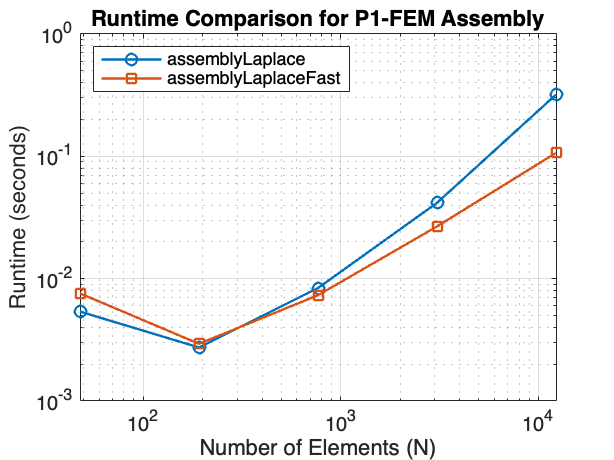


figure;
loglog(number_of_elements, timeLaplace, 'o-', 'LineWidth',1.2); hold on;
loglog(number_of_elements, timeLaplaceFast, 's-', 'LineWidth',1.2);
grid on;
xlabel('Number of Elements (N)');
ylabel('Runtime (seconds)');
legend('assemblyLaplace','assemblyLaplaceFast','Location','NorthWest');
title('Runtime Comparison for P1-FEM Assembly');

## Assembly Laplace Usual

This function builds the P1-FEM matrix for the 2D Poisson problem.

Even though the code appears to be of linear cost, one observes a quadratic growth of the runtime.

The function iterates over all elements and updates the sparse matrix by modifying a 3×33 block for each element, where each sparse matrix update is not constant-time due to internal data structure operations. Consequently, when these updates are performed repeatedly, the cumulative effect leads to an overall O(N^2) time complexity.

function A = assemblyLaplace(coordinates,elements)

nC = size(coordinates,1);
A = sparse(nC,nC);

for i = 1:size(elements,1)
   nodes = elements(i,:); % extracts the three global node indices that make up the current triangle
   B = [1 1 1 ; coordinates(nodes,:)']; % B is formed with the first row as all ones and the remaining rows as the coordinates of the three nodes
   grad = B \ [0 0 ; 1 0 ; 0 1]; % find gradient of B
  
   A(nodes,nodes) = A(nodes,nodes) + det(B)*(grad*grad')/2; % adds the computed local stiffness matrix to the global matrix A at the positions corresponding to the current triangle s nodes.
end

end

## Assembly Laplace Fast

We aim to build the P1-FEM matrix for the 2D Poisson problem in (almost) linear complexity.

Instead of updating the matrix, in the element loop below, we will build vectors of these updates. 

Later we can then use the full power of the sparse command to build the P1-FEM matrix.

The key idea is that in a FEM for the Laplace. each element has 3 nodes, and each element produces a local 3×3 stiffness matrix. That 3×3 matrix has 9 entries. When we “assemble” the global stiffness matrix, we need to add these 9 contributions into the appropriate places in the global matrix. 

The code does this by preallocating three vectors (I, J, and A) of length 9×(number of elements) and then filling them in for each element.

function A = assemblyLaplaceFast(coordinates,elements)

nC = size(coordinates,1);
I = zeros(9*nC,1); % long arrays 
J = zeros(9*nC,1);
A = zeros(9*nC,1);


for i = 1:size(elements,1)
   nodes = elements(i,:); % extracts the three global node indices that make up the current triangle
   B = [1 1 1 ; coordinates(nodes,:)']; % B is formed with the first row as all ones and the remaining rows as the coordinates of the three nodes
   grad = B \ [0 0 ; 1 0 ; 0 1]; % find gradient of B

   Alocal = det(B)*(grad*grad')/2; % calculates the element (local) stiffness matrix

   I(1+9*(i-1): 9*i) = reshape(repmat(nodes,3,1),9,1); %???

   % (nodes,3,1) is a 1×3 vector containing the global node numbers for that element.
   % repmat(nodes,3,1)  creates a 3×3 matrix where each of the 3 rows is the vector nodes
   % reshape(): This converts the 3×3 matrix into a 9×1 column vector 

   J(1+9*(i-1): 9*i) = reshape(repmat(nodes',1,3),9,1);%?
   % repmat(nodes,3,1) 
   % creates a 3×3 matrix where the column is repeated three times

   A(1+9*(i-1):9*i) = Alocal(:); %?
end

% Now, we can build the matrix by means of sparse:
A = sparse(I,J,A,nC,nC); %  constructs the global stiffness matrix 
end

function [coordinates,newElements,varargout] = myrefine(coordinates,nodes,varargin)
%refineRGB: local refinement of finite element mesh by red-green-blue
%           refinement, where marked nodes are red-refined.
%
%Usage:
%
%[coordinates,nodes,edges,neumann] = refineRGB(coordinates,nodes,edges,neumann,marked)
% 
%    refineRGB expects as input a finite element mesh described by the 
%    fields coordinates, nodes, edges and neumann. The vector 
%    marked contains the indices of nodes which are refined by
%    red-refinement, i.e. which are split into 4 similar triangles.
% 
%    The function returns the refined mesh in terms of the same data as
%    for the input.
%
%Remark:
%
%    This program is a supplement to the paper 
%    >> Efficient Implementation of Adaptive P1-FEM in Matlab <<
%    by S. Funken, D. Praetorius, and P. Wissgott. The reader should 
%    consult that paper for more information.   
%
%Authors:
% 
%    S. Funken, D. Praetorius, P. Wissgott  10-07-08

    markedElements = varargin{end};
    number_of_nodes = size(nodes,1);
    %*** Sort nodes such that first edge is longest
    dx = coordinates(nodes(:,[2,3,1]),1)-coordinates(nodes,1);
    dy = coordinates(nodes(:,[2,3,1]),2)-coordinates(nodes,2);
    [hT,idxMax] = max(reshape(dx.^2+dy.^2,number_of_nodes,3),[],2);
    idx = ( idxMax==2 );
    nodes(idx,:) = nodes(idx,[2,3,1]); 
    idx = ( idxMax==3 );
    nodes(idx,:) = nodes(idx,[3,1,2]); 
    %*** Obtain geometric information on edges
    [edge2nodes,element2edges,boundary2edges{1:nargin-3}] = provideGeometricData(nodes,varargin{1:end-1});
    %*** Mark edges for refinement
    edge2newNode = zeros(max(max(element2edges)),1);
    edge2newNode(element2edges(markedElements,:)) = 1;
    swap = 1;
    while ~isempty(swap)
        markedEdge = edge2newNode(element2edges);
        swap = find( ~markedEdge(:,1) & (markedEdge(:,2) | markedEdge(:,3)) );
        edge2newNode(element2edges(swap,1)) = 1;
    end
    %*** Generate new nodes
    edge2newNode(find(edge2newNode)) = size(coordinates,1) + [1:nnz(edge2newNode)];
    idx = find(edge2newNode);
    coordinates(edge2newNode(idx),:) = (coordinates(edge2nodes(idx,1),:)+coordinates(edge2nodes(idx,2),:))/2;
    %*** Refine boundary conditions
    for j = 1:nargout-2
        boundary = varargin{j};
        if ~isempty(boundary)
            newNodes = edge2newNode(boundary2edges{j});
            markedEdges = find(newNodes);
            if ~isempty(markedEdges)
                boundary = [boundary(~newNodes,:); ...
                            boundary(markedEdges,1),newNodes(markedEdges); ...
                            newNodes(markedEdges),boundary(markedEdges,2)];
            end
        end
        varargout{j} = boundary;
    end
    %*** Provide new nodes for refinement of nodes
    newNodes = edge2newNode(element2edges);
    %*** Determine type of refinement for each element
    markedEdges = (newNodes~=0);
    none = ~markedEdges(:,1);
    bisec1  = ( markedEdges(:,1) & ~markedEdges(:,2) & ~markedEdges(:,3) );
    bisec12 = ( markedEdges(:,1) &  markedEdges(:,2) & ~markedEdges(:,3) );
    bisec13 = ( markedEdges(:,1) & ~markedEdges(:,2) &  markedEdges(:,3) );
    red     = ( markedEdges(:,1) &  markedEdges(:,2) &  markedEdges(:,3) );
    %*** Generate element numbering for refined mesh
    idx = ones(number_of_nodes,1);
    idx(bisec1)  = 2; %*** green = newest vertex bisection of 1st edge
    idx(bisec12) = 3; %*** blue (right) = newest vertex bisection of 1st and 2nd edge
    idx(bisec13) = 3; %*** blue (left) = newest vertex bisection of 1st and 3rd edge
    idx(red)     = 4; %*** red refinement
    idx = [1;1+cumsum(idx)];
    %*** Generate new nodes
    newElements = zeros(idx(end)-1,3);
    newElements(idx(none),:) = nodes(none,:);
    newElements([idx(bisec1),1+idx(bisec1)],:) = [nodes(bisec1,3),nodes(bisec1,1),newNodes(bisec1,1); ...
                                                  nodes(bisec1,2),nodes(bisec1,3),newNodes(bisec1,1)];
    newElements([idx(bisec12),1+idx(bisec12),2+idx(bisec12)],:) = [nodes(bisec12,3),nodes(bisec12,1),newNodes(bisec12,1); ...
                                                                    newNodes(bisec12,1),nodes(bisec12,2),newNodes(bisec12,2); ...
                                                                    nodes(bisec12,3),newNodes(bisec12,1),newNodes(bisec12,2)]; 
    newElements([idx(bisec13),1+idx(bisec13),2+idx(bisec13)],:) = [newNodes(bisec13,1),nodes(bisec13,3),newNodes(bisec13,3); ...
                                                                    nodes(bisec13,1),newNodes(bisec13,1),newNodes(bisec13,3); ...
                                                                    nodes(bisec13,2),nodes(bisec13,3),newNodes(bisec13,1)];
    newElements([idx(red),1+idx(red),2+idx(red),3+idx(red)],:) = [nodes(red,1),newNodes(red,1),newNodes(red,3); ...
                                                                    newNodes(red,1),nodes(red,2),newNodes(red,2); ...
                                                                    newNodes(red,3),newNodes(red,2),nodes(red,3); ...
                                                                    newNodes(red,2),newNodes(red,3),newNodes(red,1)];
end


function [edge2nodes,element2edges,varargout] = provideGeometricData(nodes,varargin)
%
%provideGeometricData: returns geometric data for finite element mesh
%
%Usage:
%
%[edges2nodes,element2edges,dirichlet2edges,neumann2edges] = provideGeometricData(nodes,edges,neumann)
%
%Comments:
%
%    provideGeometricData expects as input a finite element mesh described
%    by the fields nodes, edges, and neumann. The
%    function chooses a numbering of the edges and then returns this numbering
%    related to nodes, edges, and the boundary conditions.
%
%    edges2nodes(k) returns the indices of the two nodes of the k-th edge.
%    element2edges(j,k) provides the edge number of the edge between the two 
%    nodes nodes(j,k) and nodes(j,k+1). dirichlet2edges(k) provides
%    the number of the k-th Dirichlet edge given by edges(k,:). The same
%    applies for neumann2edges
%
%Remark:
%
%    This program is a supplement to the paper 
%    >> Efficient Implementation of Adaptive P1-FEM in Matlab <<
%    by S. Funken, D. Praetorius, and P. Wissgott. The reader should 
%    consult that paper for more information.   
%
%Authors:
% 
%    S. Funken, D. Praetorius, P. Wissgott  10-07-08

number_of_nodes = size(nodes,1);
nB = nargin-1;

%*** Node vectors of all edges (interior edges appear twice) 
I = nodes(:);
J = reshape(nodes(:,[2,3,1]),3*number_of_nodes,1);

%*** Symmetrize I and J (so far boundary edges appear only once)
pointer = [1,3*number_of_nodes,zeros(1,nB)];
for j = 1:nB
    boundary = varargin{j};
    if ~isempty(boundary)
        I = [I; boundary(:,2)];
        J = [J; boundary(:,1)];
    end
    pointer(j+2) = pointer(j+1) + size(boundary,1);
end

%*** Create numbering of edges
idxIJ = find(I < J);
edgeNumber = zeros(length(I),1);
edgeNumber(idxIJ) = 1:length(idxIJ);
idxJI = find(I > J);
number2edges = sparse(I(idxIJ),J(idxIJ),1:length(idxIJ));
[foo{1:2},numberingIJ] = find(number2edges);
[foo{1:2},idxJI2IJ] = find(sparse(J(idxJI),I(idxJI),idxJI));
edgeNumber(idxJI2IJ) = numberingIJ;

%*** Provide element2edges and edge2nodes
element2edges = reshape(edgeNumber(1:3*number_of_nodes),number_of_nodes,3);
edge2nodes = [I(idxIJ),J(idxIJ)];

%*** Provide boundary2edges
for j = 1:nB
    varargout{j} = edgeNumber(pointer(j+1)+1:pointer(j+2));
end
end
